AOA = [0, 5, 10, 15];                               % Alpha (Angle of attack) 
p = 1.204;                                          % Density of the air fluid kg/m3
v = 24;                                             % Free stream Velocity m/s
u = (1.81*10^-5);                                   %  Flow speed (Velocity) m/s2
c = 0.089;                                          % Airfoil Chord m
Re = (v*p*c)/u;                                     %  Reynolds number
disp(['Reynolds numbers at transition = ' num2str(Re) ]); 

Reynolds numbers at transition = 142085.3039


Patm = 101400;                                      % Atmpsoheric pressure Pa
Pwindym = 354;                                      % Wind tunnel dynamic pressure Pa
P0s = Patm - Pwindym;                               % Static pressure inside wind tunnel Pa
Pdym = 0.5*p*(v^2);                                 % Bernoulli's equation to determine Dynamic pressure Pa                
P = 1000;                                           %  density of the liquid manometer fluid kg/m3
g = 9.81;                                           %  Gravitational force m/s2

xx0U = [0 ,5 ,10 ,20, 30 ,40, 50 ,60 ,70 ,80,5, 10, 20 ,30, 40, 50 ,60, 70, 80]; % Position
x0u = [5 ,10 ,20, 30 ,40, 50 ,60 ,70 ,80];        % Upper  position %
x0l = [5, 10, 20 ,30, 40, 50 ,60, 70, 80];        % Lower  position %
XX0U = xx0U/100;
X0u = x0u/100;
X0l = x0l/100; 
x0 = X0u*c;                                            % The distance from leading edge to pressure difference location m
dc = [0.00445, 0.00445, 0.0089, 0.0089, 0.0089, 0.0089, 0.0089, 0.0089, 0.0089]; % differential of chord
X0CU = XX0U/c;                                        % Chord ratio m  
x0cu = X0CU([1,2]);
Xu = x0u/100;
Xl = x0l/100;
xcu = Xu/c;
xcl = Xl/c;

% At 0 AOA
h0 = [0,2.32,2.69,2.93,2.7,2.54,2.41,2.35,2.13,1.66,1.69,1.59,1.45,1.46,1.42,1.41,1.4,1.39,1.38 ];
H0 = 0.0254 * h0; 
h0u = [2.32,2.69,2.93,2.7,2.54,2.41,2.35,2.13,1.66];        %  Liquid height of pitot tube connected to the upper surface inches 
h0l = [1.69,1.59,1.45,1.46,1.42,1.41,1.4,1.39,1.38 ]; %  Liquid height of pitot tube connected to the lower surface inches 
H0u = 0.0254*h0u;                                   %  Convert from inches to meters
H0l = 0.0254*h0l;                                   %  Convert from inches to meters
Ps0 = (Patm - (P*g*H0))                            % Static pressure on airfoil surface

Ps0 = 	1.0e+05 *

    1.0140    1.0082    1.0073    1.0067    1.0073    1.0077    1.0080    1.0081    1.0087    1.0099    1.0098    1.0100    1.0104    1.0104    1.0105    1.0105    1.0105    1.0105    1.0106


P0st2 = (Patm - (P*g*H0l));                         % Lower static surface pressure Pa
P0st = (Patm - (P*g*H0u));                          % Upper static surface pressure Pa
C0P = (Ps0-P0s)/Pwindym                                % pressure coefficient Pa

C0P =     1.0000   -0.6330   -0.8934   -1.0624   -0.9005   -0.7879   -0.6964   -0.6541   -0.4993   -0.1684   -0.1896   -0.1192   -0.0206   -0.0277    0.0005    0.0075    0.0146    0.0216    0.0286


c0p = C0P([1,2]);
CP0 = (P0st-P0s)/Pwindym;
CP02 = (P0st2-P0s)/Pwindym;
cup = CP02(1)

cup = -0.1896

c0p2 = [C0P(1),cup]

c0p2 =     1.0000   -0.1896


P0d = P0st2 - P0st                                  % Pressure difference

P0d =   156.9796  274.0914  368.7775  308.9758  279.0749  249.1740  236.7153  184.3888   69.7687


F0n = sum(P0d .* dc)                                       % Normal force acting on a wing N

F0n = 17.0205

C0n = (1/c)*(sum((P0d/Pwindym).*dc))                  % Normal force coefficient

C0n = 0.5402

C0l = C0n * cosd(10)                                 % Lift coefficient      

C0l = 0.5320

C0mle = (-1/c^2)*(sum(((P0d/Pwindym).*x0).*dc))             % Quarter chord moment

C0mle = -0.2111

X0cp = (-1)*((C0mle/C0n)*c)                         % Center of pressure location @ 0 degree AOA

X0cp = 0.0348

 disp(['Center of pressure at 0° AOA = ' num2str(X0cp)])

Center of pressure at 0° AOA = 0.034774


C0m4u = (C0n/4)+C0mle                                  % Moment along quater chord

C0m4u = -0.0760

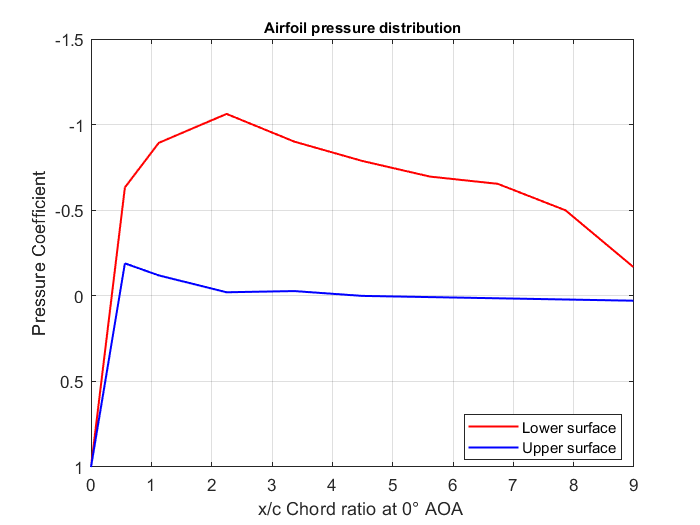


plot(x0cu,c0p,'r',xcu, CP0,'r',x0cu, c0p2,'b', xcl, CP02,'b','linewidth',1.2)
set(gca,'YDir','reverse')
title('Airfoil pressure distribution','FontSize',9);    % use for title positioning
xlabel('x/c Chord ratio at 0° AOA ');
ylabel('Pressure Coefficient');
legend({'Lower surface';'';'Upper surface'},'Location','best');
grid on


% At 5 AOA
h5 = [1.13,4.02,3.93,3.71,3.35,3.23,2.52,2.32,2.07,1.78,0.72,0.9,1.03,1.09,1.12,1.18,1.2,1.24,1.28 ];
H5 = 0.0254 * h5; 
h5u = [4.02,3.93,3.71,3.35,3.23,2.52,2.32,2.07,1.78];        %  Liquid height of pitot tube connected to the upper surface inches 
h5l = [0.72,0.9,1.03,1.09,1.12,1.18,1.2,1.24,1.28 ]; %  Liquid height of pitot tube connected to the lower surface inches 
H5u = 0.0254*h5u;                                   %  Convert from inches to meters
H5l = 0.0254*h5l;                                   %  Convert from inches to meters
Ps5 = (Patm - (P*g*H5))                            % Static pressure on airfoil surface  

Ps5 = 	1.0e+05 *

    1.0112    1.0040    1.0042    1.0048    1.0057    1.0060    1.0077    1.0082    1.0088    1.0096    1.0122    1.0118    1.0114    1.0113    1.0112    1.0111    1.0110    1.0109    1.0108


P5st = (Patm - (P*g*H5u));                          % Upper static surface pressure Pa
P5st2 = (Patm - (P*g*H5l));                         % Lower static surface pressure Pa
C5P = (Ps5-P0s)/Pwindym                               % pressure coefficient Pa

C5P =     0.2046   -1.8296   -1.7663   -1.6114   -1.3580   -1.2735   -0.7738   -0.6330   -0.4570   -0.2529    0.4932    0.3665    0.2750    0.2328    0.2117    0.1694    0.1553    0.1272    0.0990


c5p = C5P([1,2]);
CP5 = (P5st-P0s)/Pwindym;                                % Upper pressure coefficient Pa
CP52 = (P5st2-P0s)/Pwindym;                                % Lower pressure coefficient Pa
cup5 = CP52(1)

cup5 = 0.4932

c5p2 = [C5P(1),cup5]

c5p2 =     0.2046    0.4932


P5d = P5st2 - P5st ;                                % Pressure difference
F5n = sum(P5d .* dc)                                        % Normal force acting on a wing N

F5n = 31.0582

C5n = (1/c)*(sum((P5d/Pwindym).*dc))                           % Normal force coefficient

C5n = 0.9858

C5l = C5n * cosd(10)                                 % Lift coefficient      

C5l = 0.9708

C5mle = (-1/c^2)*(sum(((P5d/Pwindym).*x0).*dc))                    % Quarter chord moment

C5mle = -0.3248

X5cp = (-1)*((C5mle/C5n)*c)                         % Center of pressure location @ 0 degree AOA

X5cp = 0.0293

 disp(['Center of pressure at 5° AOA = ' num2str(X5cp)])

Center of pressure at 5° AOA = 0.029328


C5m4u = (C5n/4)+C5mle                                  % Moment along quater chord

C5m4u = -0.0784

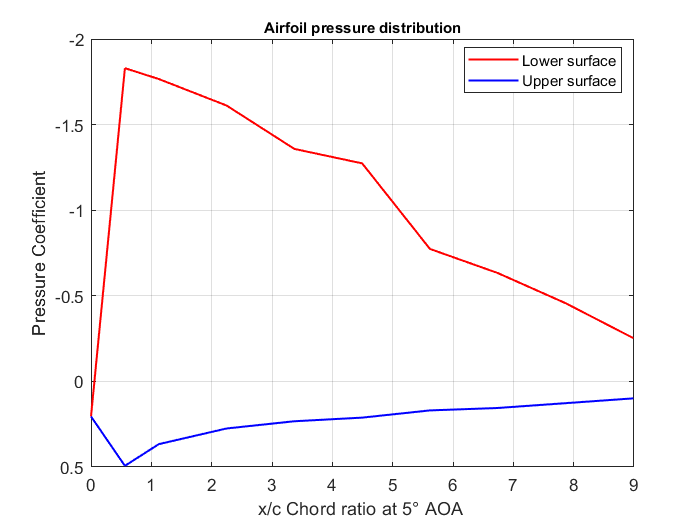


plot(x0cu,c5p,'r',xcu, CP5,'r',x0cu, c5p2,'b',xcl, CP52,'b','linewidth',1.2)
set(gca,'YDir','reverse')
title('Airfoil pressure distribution','FontSize',9);    % use for title positioning
xlabel('x/c Chord ratio at 5° AOA ');
ylabel('Pressure Coefficient');
legend({'Lower surface';'';'Upper surface'},'Location','best');
grid on


% At 10 AOA
h10 = [4.09,5.69,5.03,4.43,3.8,3.1,2.75,2.38,2.01,1.7,0.24,0.46,0.71,0.83,0.91,0.99,1.08,1.13,1.2 ];
H10 = 0.0254 * h10; 
h10u = [5.69,5.03,4.43,3.8,3.1,2.75,2.38,2.01,1.7];        %  Liquid height of pitot tube connected to the upper surface inches 
h10l =[0.24,0.46,0.71,0.83,0.91,0.99,1.08,1.13,1.2 ]; %  Liquid height of pitot tube connected to the lower surface inches 
H10u = 0.0254*h10u;                                   %  Convert from inches to meters
H10l = 0.0254*h10l;                                   %  Convert from inches to meters
Ps10 = (Patm - (P*g*H10))                            % Static pressure on airfoil surface  

Ps10 = 	1.0e+05 *

    1.0038    0.9998    1.0015    1.0030    1.0045    1.0063    1.0071    1.0081    1.0090    1.0098    1.0134    1.0129    1.0122    1.0119    1.0117    1.0115    1.0113    1.0112    1.0110


P10st = (Patm - (P*g*H10u));                          % Upper static surface pressure Pa
P10st2 = (Patm - (P*g*H10l));                         % Lower static surface pressure Pa
C10P = (Ps10-P0s)/Pwindym                                 % Pressure coefficient Pa

C10P =    -1.8789   -3.0051   -2.5405   -2.1182   -1.6747   -1.1820   -0.9357   -0.6752   -0.4148   -0.1966    0.8311    0.6762    0.5002    0.4158    0.3595    0.3032    0.2398    0.2046    0.1553


c10p = C10P([1,2]);
CP10 = (P10st-P0s)/Pwindym;                                % Upper pressure coefficient Pa
CP102 = (P10st2-P0s)/Pwindym;                                % Lower pressure coefficient Pa
cup10 = CP102(1);
c10p2 = [C10P(1),cup10];
P10d = P10st2 - P10st ;                                % Pressure difference
F10n = sum(P10d .* dc)                                        % Normal force acting on a wing N

F10n = 40.6495

C10n = (1/c)*(sum((P10d/Pwindym).*dc))                            % Normal force coefficient

C10n = 1.2902

C10l = C10n * cosd(10)                                 % Lift coefficient      

C10l = 1.2706

C10mle = (-1/c^2)*(sum(((P10d/Pwindym).*x0).*dc))                      % Quarter chord moment

C10mle = -0.3908

X10cp = (-1)*((C10mle/C10n)*c)                         % Center of pressure location @ 0 degree AOA

X10cp = 0.0270

 disp(['Center of pressure at 10° AOA = ' num2str(X10cp)])

Center of pressure at 10° AOA = 0.026956


C10m4u = (C10n/4)+C10mle                                  % Moment along quater chord

C10m4u = -0.0682

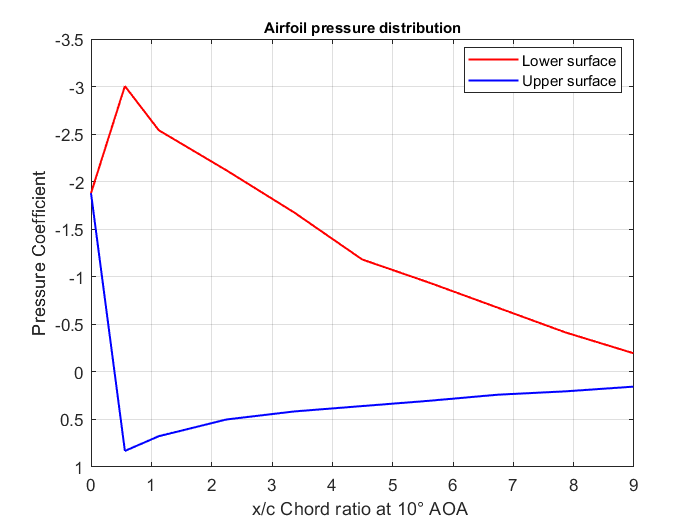



plot(x0cu,c10p,'r',xcu, CP10,'r',x0cu, c10p2,'b',xcl, CP102,'b','linewidth',1.2)
set(gca,'YDir','reverse')
title('Airfoil pressure distribution','FontSize',9);    % use for title positioning
xlabel('x/c Chord ratio at 10° AOA ');
ylabel('Pressure Coefficient'); 
legend({'Lower surface';'';'Upper surface'},'Location','best');
grid on


% At 15 AOA
h15 = [6.7,6.5,5.93,4.2,3.98,2.88,2.3,1.9,1.84,1.3,0,0.24,0.5,0.7,0.84,0.9,1.02,1.12,1.24];
H15 = 0.0254 * h15; 
h15u = [6.5,5.93,4.2,3.98,2.88,2.3,1.9,1.84,1.3];        %  Liquid height of pitot tube connected to the upper surface inches 
h15l = [0,0.24,0.5,0.7,0.84,0.9,1.02,1.12,1.24]; %  Liquid height of pitot tube connected to the lower surface inches 
H15u = 0.0254*h15u;                                   %  Convert from inches to meters
H15l = 0.0254*h15l;                                   %  Convert from inches to meters
Ps15 = (Patm - (P*g*H15))                            % Static pressure on airfoil surface  

Ps15 = 	1.0e+05 *

    0.9973    0.9978    0.9992    1.0035    1.0041    1.0068    1.0083    1.0093    1.0094    1.0108    1.0140    1.0134    1.0128    1.0123    1.0119    1.0118    1.0115    1.0112    1.0109


P15st = (Patm - (P*g*H15u));                          % Upper static surface pressure Pa
P15st2 = (Patm - (P*g*H15l));                         % Lower static surface pressure Pa
C15P = (Ps15-P0s)/Pwindym                                 % Pressure coefficient Pa

C15P =    -3.7160   -3.5752   -3.1740   -1.9563   -1.8014   -1.0272   -0.6189   -0.3374   -0.2951    0.0850    1.0000    0.8311    0.6481    0.5073    0.4087    0.3665    0.2820    0.2117    0.1272


c15p = C15P([1,2]);
CP15 = (P15st-P0s)/Pwindym;                                % Upper pressure coefficient Pa
CP152 = (P15st2-P0s)/Pwindym;                                % Lower pressure coefficient Pa
cup15 = CP152(1)

cup15 = 1

c15p2 = [C15P(1),cup15]

c15p2 =    -3.7160    1.0000


P15d = P15st2 - P15st ;                                   % Pressure difference
F15n = sum(P15d .* dc)                                        % Normal force acting on a wing N

F15n = 40.3058

C15n = (1/c)*(sum((P15d/Pwindym).*dc))                            % Normal force coefficient

C15n = 1.2793

C15l = C15n * cosd(10)                                 % Lift coefficient      

C15l = 1.2599

C15mle = (-1/c^2)*(sum(((P15d/Pwindym).*x0).*dc))                      % Quarter chord moment

C15mle = -0.3355

X15cp = (-1)*((C15mle/C15n)*c)                         % Center of pressure location @ 0° AOA

X15cp = 0.0233

 disp(['Center of pressure at 15° AOA = ' num2str(X15cp)])

Center of pressure at 15° AOA = 0.023343


C15m4u = (C15n/4)+C15mle                                  % Moment along quater chord

C15m4u = -0.0157

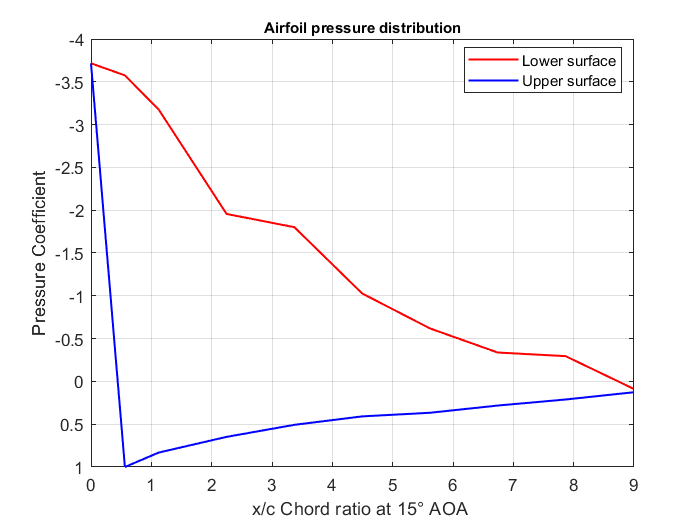


% To plot pressure distribution against chord ratio x/c at different angle of attack
plot(x0cu,c15p,'r',xcu, CP15,'r',x0cu, c15p2,'b',xcl, CP152,'b','linewidth',1.2)
set(gca,'YDir','reverse')
title('Airfoil pressure distribution','FontSize',9);    % use for title positioning
xlabel('x/c Chord ratio at 15° AOA ');
ylabel('Pressure Coefficient');
legend({'Lower surface';'';'Upper surface'},'Location','best');
grid on



% To determine flow velocity behind the airfoil
hh0 = [0.1,0.1,0.1,0.1,0.1,0.6,0.5,0.2,0.12,0.10,0.10,0.1,0.1,0.1,0.1,0.10,0.1,0.1 ];  % Liquid height of pitot @ 0 AOA in inches 
hh5 = [0.1,0.1,0.1,0.1,0.1,0.14,0.75,0.56,0.2,0.1,0.1,0.1,0.1,0.1,0.1,0.1,0.1,0.1];  % Liquid height of pitot @ 5 AOA in inches 
hh10 = [0,0,0,0,0,0,0.21,0.9,0.76,0.33,0.07,0.05,0.05,0.05,0.05,0.05,0.05,0.05 ];  % Liquid height of pitot @ 10 AOA  in inches 
hh15 = [0,0,0,0,0,0,0.13,0.42,1.27,1.5,1.35,0.6,0.22,0.12,0.12,0.10,0.1,0.1 ];  % Liquid height of pitot @ 15 AOA in inches 
ha0 = hh0 * 0.0254;                           % Convert to meters 
ha5 = hh5 * 0.0254;                           % Convert to meters 
ha10 = hh10 * 0.0254;                           % Convert to meters 
ha15 = hh15 * 0.0254;                           % Convert to meters 

PT0a = (Patm - (P*g*ha0));           % Full pressure of pitot tube  Pa
PT5a = (Patm - (P*g*ha5));           % Full pressure of pitot tube  Pa
PT10a = (Patm - (P*g*ha10));           % Full pressure of pitot tube  Pa
PT15a = (Patm - (P*g*ha15));           % Full pressure of pitot tube  Pa
P0dyma = PT0a - P0s                  % Dynamic pressure behind the airfoil @ 0°  Pa

P0dyma =   329.0826  329.0826  329.0826  329.0826  329.0826  204.4956  229.4130  304.1652  324.0991  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826


P5dyma = PT5a - P0s                  % Dynamic pressure behind the airfoil @ 5° Pa

P5dyma =   329.0826  329.0826  329.0826  329.0826  329.0826  319.1156  167.1195  214.4626  304.1652  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826  329.0826


P10dyma = PT10a - P0s                 % Dynamic pressure behind the airfoil @ 10° Pa

P10dyma =   354.0000  354.0000  354.0000  354.0000  354.0000  354.0000  301.6735  129.7434  164.6278  271.7726  336.5578  341.5413  341.5413  341.5413  341.5413  341.5413  341.5413  341.5413


P15dyma = real(PT15a - P0s)                  % Dynamic pressure behind the airfoil @ 15° Pa

P15dyma =   354.0000  354.0000  354.0000  354.0000  354.0000  354.0000  321.6074  249.3469   37.5490  -19.7610   17.6151  204.4956  299.1817  324.0991  324.0991  329.0826  329.0826  329.0826



Va0 = sqrt((2*P0dyma)./p);          % Flow Velocity behind the airfoil @ 0° m/s
Va5 = sqrt((2*P5dyma)./p);           % Flow Velocity behind the airfoil @ 5° m/s
Va10 = sqrt((2*P10dyma)./p);           % Flow Velocity behind the airfoil @ 10° m/s
Va15 = sqrt((2*P15dyma)./p);           % Flow Velocity behind the airfoil @ 15° m/s

VA0 = real(Va0);
VA5 = real(Va5);
VA10 = real(Va10)

VA10 =    24.2495   24.2495   24.2495   24.2495   24.2495   24.2495   22.3857   14.6806   16.5369   21.2473   23.6446   23.8190   23.8190   23.8190   23.8190   23.8190   23.8190   23.8190


VA15 = real(Va15);

dy = 0.045/18;
D0 = p*(sum((VA0.*(v-VA0).*dy)))                           % Drag force for unit length

D0 = 1.3411

D5 = p*(sum((VA5.*(v-VA5).*dy)))                          % Drag force for unit length

D5 = 1.4402

D10 = p*(sum((VA10.*(v-VA10).*dy)))                       % Drag force for unit length

D10 = 1.0750

D15 = p*(sum((VA15.*(v-VA15).*dy)))                       % Drag force for unit length

D15 = 1.5270

C0d = (1/c)*(sum((sqrt((Pwindym - P0dyma)./P0dyma)).*dy));  % Drag coefficient 
C5d = (1/c)*(sum((sqrt((Pwindym - P5dyma)./P5dyma)).*dy));  % Drag coefficient 
C10d = (1/c)*(sum((sqrt((Pwindym - P10dyma)./P10dyma)).*dy)); % Drag coefficient 
C15d = real((1/c)*(sum((sqrt((Pwindym - P15dyma)./P15dyma)).*dy)));  % Drag coefficient 

Cdu = [C0d,C5d,C10d,C15d]

Cdu =     0.1728    0.1812    0.1382    0.3077



% To determine wind tunnel wall corrections

A = 0.26;                                         % Body shape factor
h = 0.305;                                        % Height of wind tunnel test section m
o = ((pi^2)/48)*((c/h)^2)

o = 0.0175

k = pi

k = 3.1416

sb = A*o;                                          % Solid blockage factor
wb = ((c/h)/2)*Cdu;                                % Wake blockade factor
b = sb + wb;                                       % Total Blockage factor
       

% To calculate corrected value

C1m4u = [C0m4u, C5m4u, C10m4u, C15m4u];
XCP = [X0cp, X5cp, X10cp, X15cp];
Clu = [C0l, C5l, C10l, C15l];
Cl = Clu.*(1-o-(2*b))                              % lift coeeficient

Cl =     0.4910    0.8936    1.1856    1.1132


C1m4 = (C1m4u.*(1-(2*b)))+(0.25*o*Cl)              % Moment coefficient

C1m4 =    -0.0693   -0.0696   -0.0597   -0.0093


Cd = Cdu.*(1-(3*sb)-(2*wb))                        % Drag coefficient

Cd =     0.1618    0.1692    0.1307    0.2759


aoa = (AOA)+(((57.3*o)/(2*pi))*(Clu+(4*C1m4u)))

aoa =     0.0364    5.1049   10.1593   15.1911


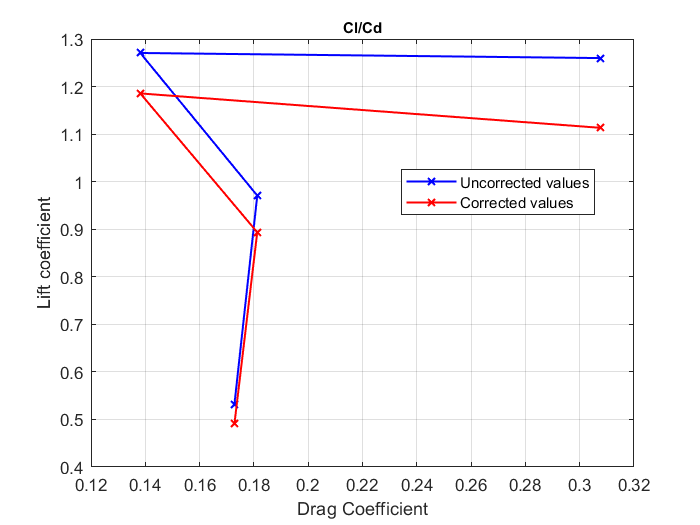



% To plot graph of Cl/Cd

plot(Cdu, Clu,'b-x', Cdu, Cl,'r-x','linewidth',1.2)
title('Cl/Cd','FontSize',9);    % use for title positioning
xlabel('Drag Coefficient');
ylabel('Lift coefficient');
legend({'Uncorrected values';'Corrected values'},'Location','best');
grid on

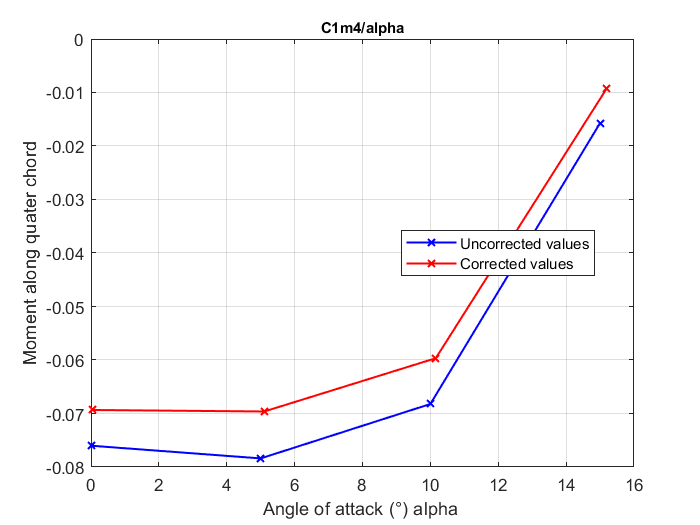


% To plot graph of Cm1/4 /alpha

plot(AOA, C1m4u,'b-x', aoa, C1m4,'r-x','linewidth',1.2)
title('C1m4/alpha','FontSize',9);    % use for title positioning
xlabel('Angle of attack (°) alpha ')
ylabel('Moment along quater chord');
legend({'Uncorrected values';'Corrected values'},'Location','best');
grid on

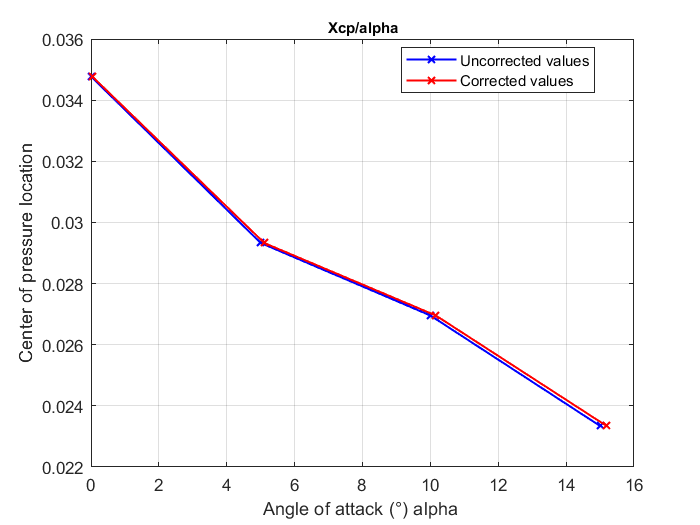



% To plot graph of Xcp/alpha

plot(AOA, XCP,'b-x', aoa ,XCP,'r-x','linewidth',1.2)
title('Xcp/alpha','FontSize',9);    % use for title positioning
xlabel('Angle of attack (°) alpha ')
ylabel('Center of pressure location');
legend({'Uncorrected values';'Corrected values'},'Location','best');
grid on

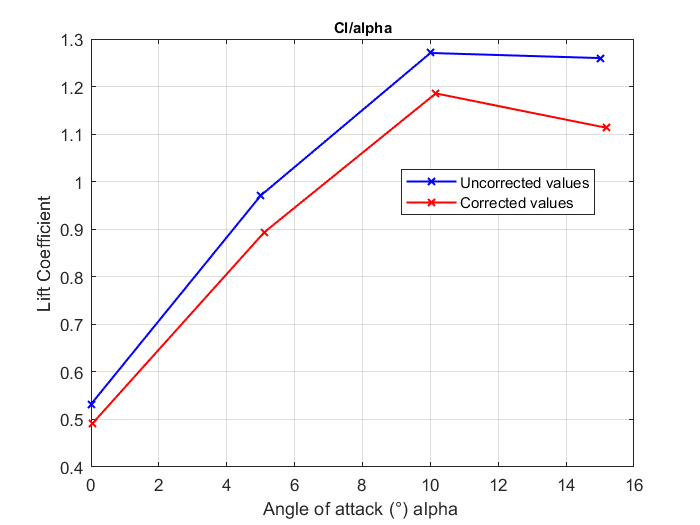


% To plot graph of Cl/alpha

plot(AOA, Clu, 'b-x', aoa, Cl,'r-x','linewidth',1.2)
title('Cl/alpha','FontSize',9);    % use for title positioning
xlabel('Angle of attack (°) alpha ')
ylabel('Lift Coefficient');
legend({'Uncorrected values';'Corrected values'},'Location','best');
grid on